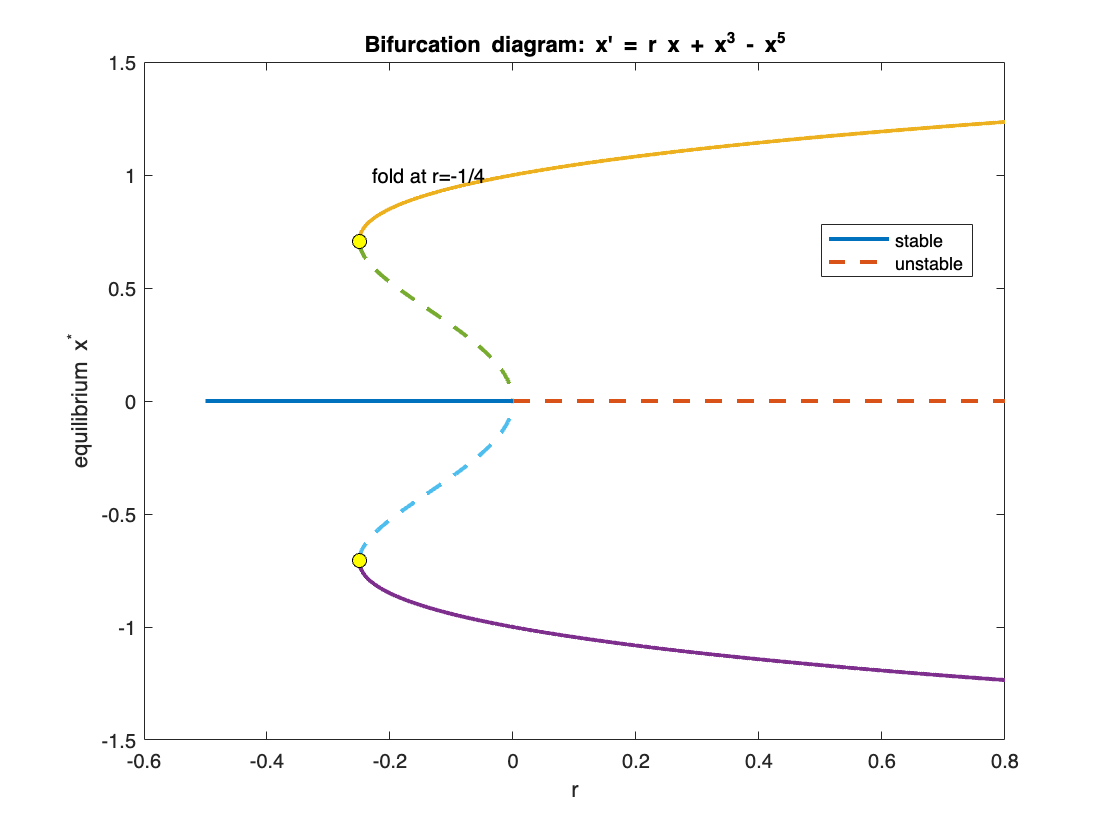

%% ================================================================
%  5) Quintic example: x' = r x + x^3 - x^5
%     Use analytic equilibria from x(r + x^2 - x^4)=0.
% ================================================================

r = linspace(-0.5,0.8,2001);

% Equilibrium at x=0 always exists.
x0 = zeros(size(r));
fx0 = r;                    % derivative f_x at x=0 is r

% Nonzero equilibria satisfy r + x^2 - x^4 = 0.
% Let u = x^2 >=0: u^2 - u - r =0 => u = (1 ± sqrt(1+4r))/2.
disc = 1 + 4*r;
hasReal = disc >= 0;

u_plus  = nan(size(r));
u_minus = nan(size(r));
u_plus(hasReal)  = (1 + sqrt(disc(hasReal)))/2;
u_minus(hasReal) = (1 - sqrt(disc(hasReal)))/2;

% Keep only positive u values
u_plus(u_plus<=0) = nan;
u_minus(u_minus<=0) = nan;

% Corresponding x equilibria (±sqrt(u))
xP1 =  sqrt(u_plus);  xP2 = -sqrt(u_plus);
xM1 =  sqrt(u_minus); xM2 = -sqrt(u_minus);

% Stability: f_x = r + 3x^2 - 5x^4
fx = @(x,rval) rval + 3*x.^2 - 5*x.^4;

figure('Name','Bifurcation: r x + x^3 - x^5','Color','w'); hold on; box on;

% plot x=0 branch stable/unstable
plot(r(fx0<0), x0(fx0<0),'LineWidth',2);     % stable for r<0
plot(r(fx0>0), x0(fx0>0),'--','LineWidth',2);% unstable for r>0

% plot nonzero branches with stability
plot_branch(r, xP1, fx(xP1,r));
plot_branch(r, xP2, fx(xP2,r));
plot_branch(r, xM1, fx(xM1,r));
plot_branch(r, xM2, fx(xM2,r));

% Mark saddle-node at r=-1/4 (disc=0)
plot(-0.25,  1/sqrt(2),'ko','MarkerFaceColor','y','MarkerSize',7);
plot(-0.25, -1/sqrt(2),'ko','MarkerFaceColor','y','MarkerSize',7);
text(-0.23, 1.0, 'fold at r=-1/4','FontSize',10);

xlabel('r'); ylabel('equilibrium x^*');
title('Bifurcation diagram: x'' = r x + x^3 - x^5');
legend('stable','unstable','Location','best');